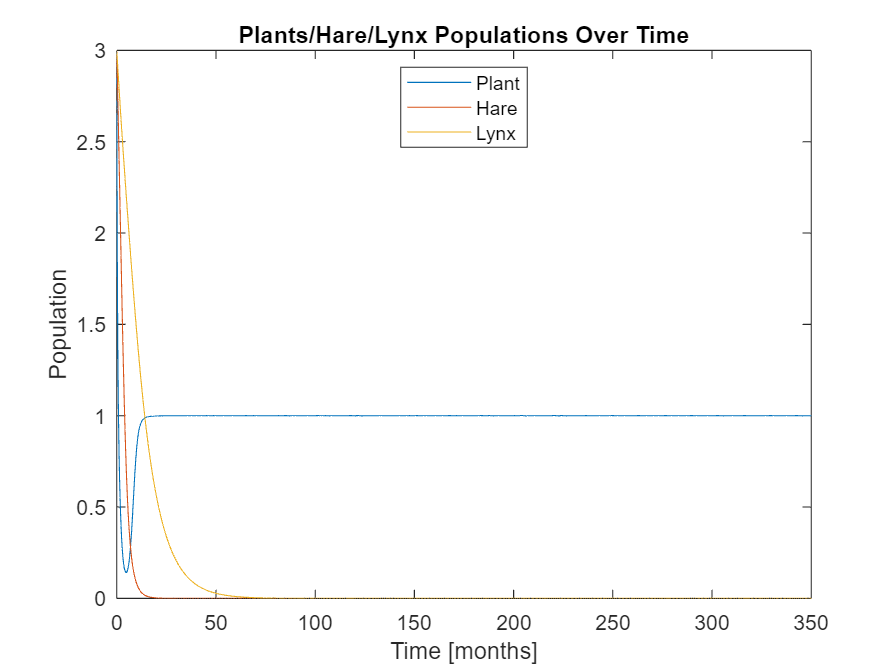

%Group Assignment The selection of variables are within the following range
%y0  = [0.1-10  0.1-10  0.1-10]; %i.e. plant, hare, lynx
%a1 = [1-10];
%a2  = [0.1-1];
%b1 = [1-10];
%b2 = [1-10];
%d1 = [0.1-1];
%d2 = [0.01-1];
%t0 = 0; 


y0  = [3  3  3]; %i.e. plant, hare, lynx
a1 = [2];
a2  = [0.2];
b1 = [5];
b2 = [5];
d1 = [0.5];
d2 = [0.1];
t0 = 0; 
tfinal=350;
tspan=[t0 tfinal];
[t,y] = ode45(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);
figure("Name",'Plant-Hare-Lynx')
plot(t,y)
title('Plants/Hare/Lynx Populations Over Time')
xlabel('Time [months]')
ylabel('Population')
legend('Plant','Hare','Lynx','Location','North')

y

y =     3.0000    3.0000    3.0000
    2.8569    2.9897    2.9960
    2.7276    2.9793    2.9921
    2.6100    2.9689    2.9881
    2.5027    2.9584    2.9842
    2.2557    2.9303    2.9736
    2.0551    2.9019    2.9631
    1.8890    2.8733    2.9527
    1.7477    2.8445    2.9422
    1.5833    2.8046    2.9279


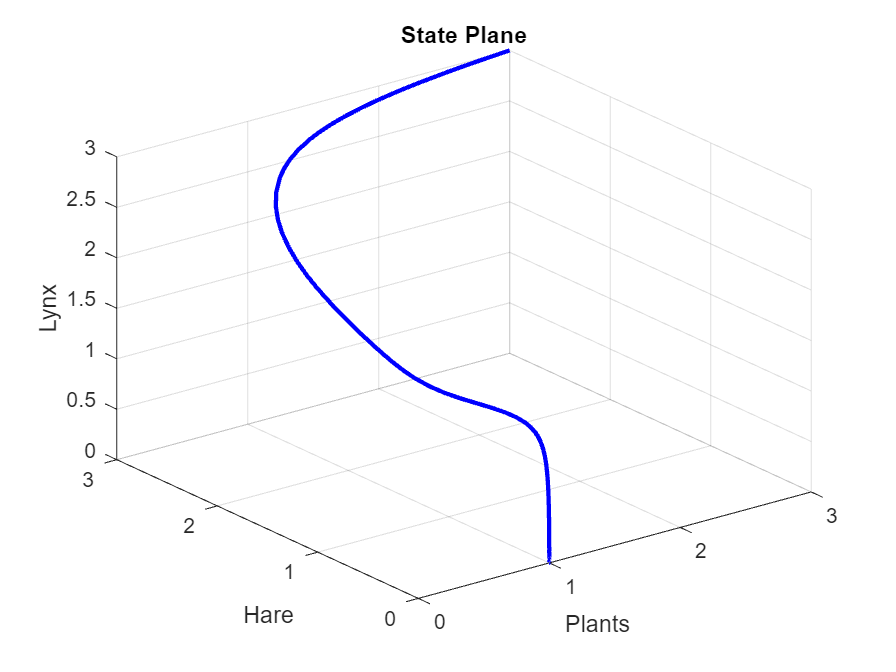

% Plot 3D curve
plot3(y(:,1), y(:,2), y(:,3), 'b', 'LineWidth', 2);
xlabel('Plants');
ylabel('Hare');
zlabel('Lynx');
title('State Plane');
grid on;

%Just ideas 
for i=1:n
    hold on
    [t,y] = ode23(@(t,y) lotka_volterra(t,y,Salpha(i),beta), tspan, y0); % simulate, note: Salpha(1) changes in each iteration!
    plot(t,y, 'Color', colors(i,:)) % plot the simulation in a color that represent the parameter value at this iteration
end

Unrecognized function or variable 'n'.

%Scenario 1: The system exhibits stable oscillations with a periodicity of approximately 70 months.
y0  = [0.75  0.15  8]; %i.e. plant, hare, lynx
a1 = [4.8];
a2  = [0.1];
b1 = [3];
b2 = [2];
d1 = [0.4];
d2 = [0.01];
t0 = 0; 
tfinal=250;
tspan=[t0 tfinal];

[t,y] = ode45(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);
figure("Name",'Plant-Hare-Lynx')
plot(t,y)
title('Plants/Hare/Lynx Populations Over Time')
xlabel('Time [months]')
ylabel('Population')
legend('Plant','Hare','Lynx','Location','North')

% Plot 3D curve
plot3(y(:,1), y(:,2), y(:,3), 'b', 'LineWidth', 2);
xlabel('Plants');
ylabel('Hare');
zlabel('Lynx');
title('State Plane');
grid on;

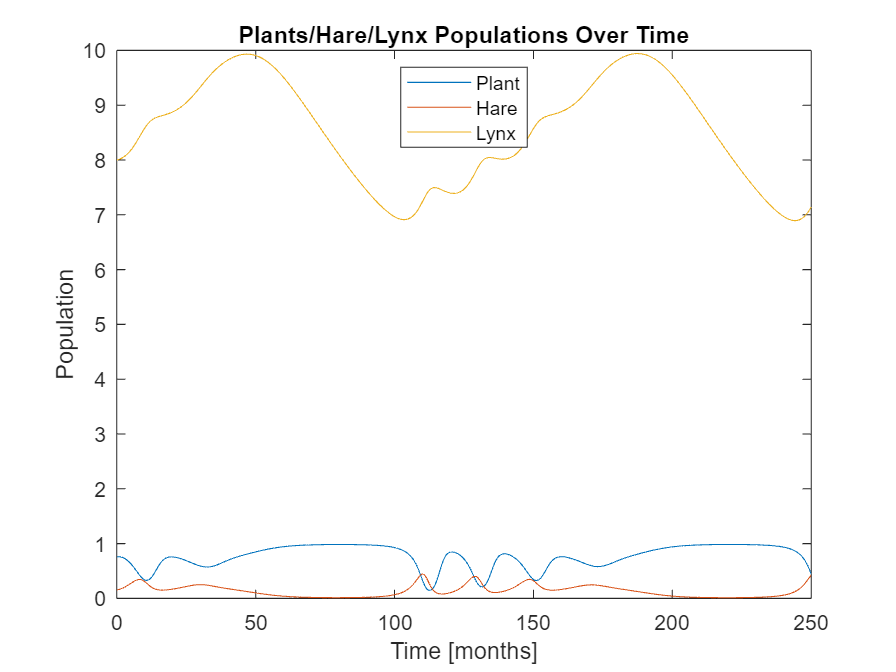


%Scenario 3: The system shows chaotic behavior and the lynx population peaks twice within the 200-months period. What makes this behavior 
% chaotic and not oscillating or random? Hint: Chaotic behavior is deterministic, sensitive to initial conditions, bounded and irregular.
y0  = [0.75  0.15  8]; %i.e. plant, hare, lynx
a1 = [4.8];
a2  = [0.1];
b1 = [3];
b2 = [2];
d1 = [0.4];
d2 = [0.01];
t0 = 0; 
tfinal=250;
tspan=[t0 tfinal];

[t,y] = ode45(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);
figure("Name",'Plant-Hare-Lynx')
plot(t,y)
title('Plants/Hare/Lynx Populations Over Time')
xlabel('Time [months]')
ylabel('Population')
legend('Plant','Hare','Lynx','Location','North')

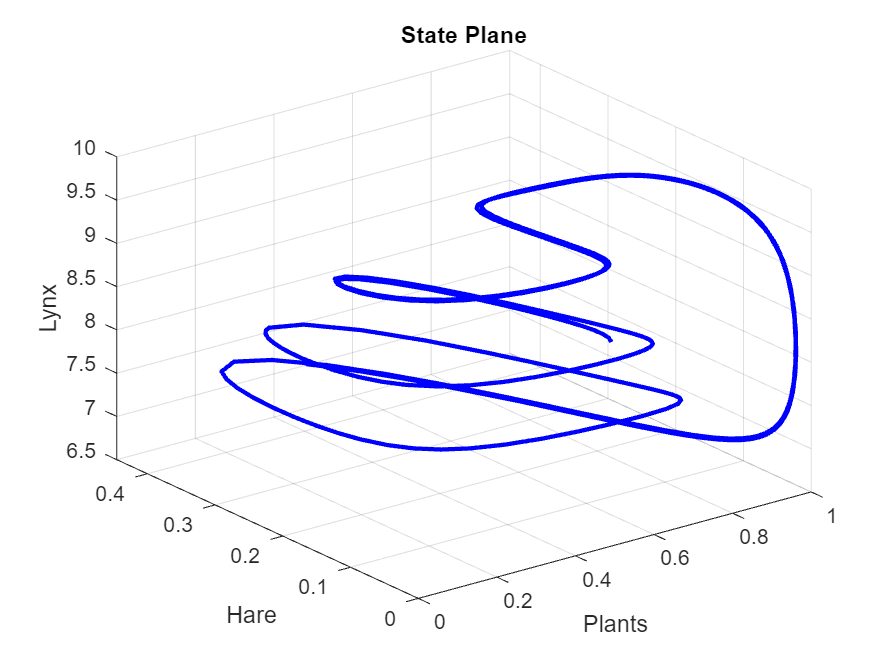


% Plot 3D curve
plot3(y(:,1), y(:,2), y(:,3), 'b', 'LineWidth', 2);
xlabel('Plants');
ylabel('Hare');
zlabel('Lynx');
title('State Plane');
grid on;